# derive_equations_JR.m

Description: Symbolically derive equations related to the jumping robot, including the full nonlinear state-space dynamics.

Inputs: none

Outputs: none

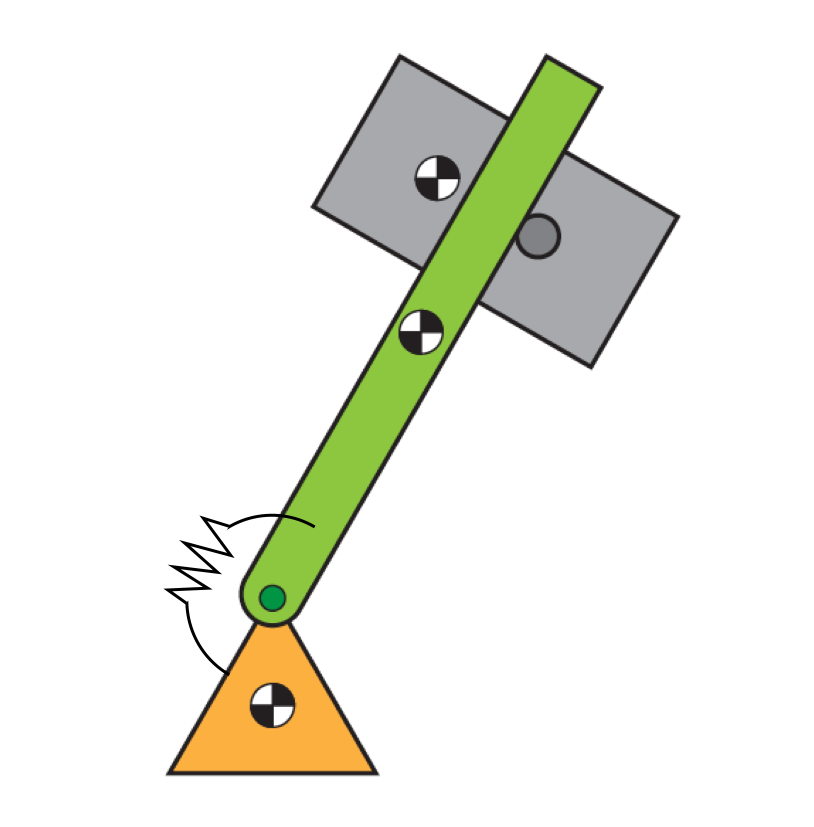

% Script Version:  derive_equations_JR_script.mxl
clear;
close all;
clc;

fprintf('Deriving jumping robot equations...\n');

Deriving jumping robot equations...


## Variable definition

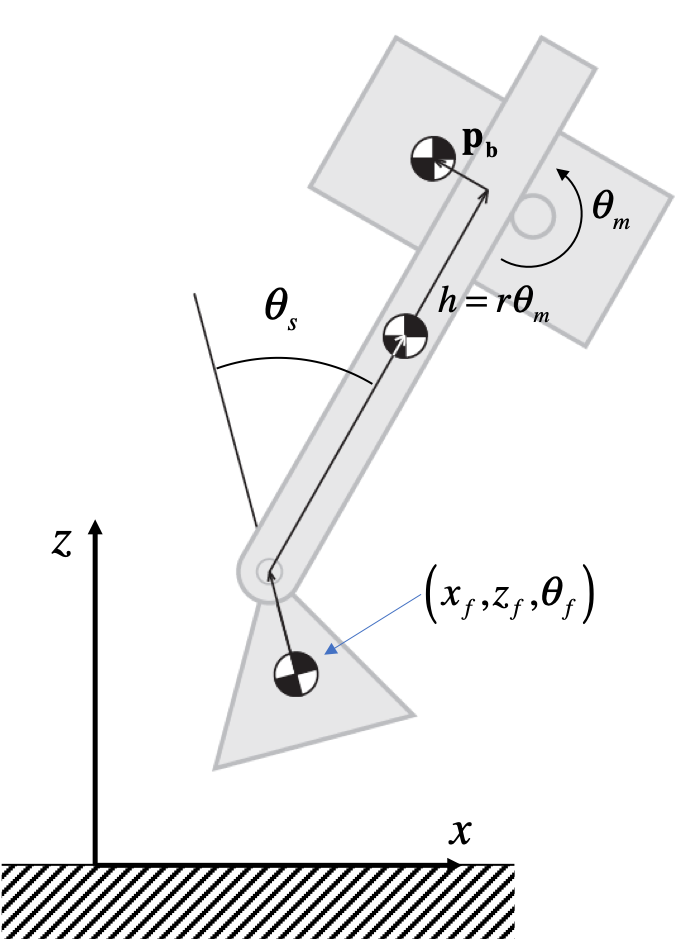 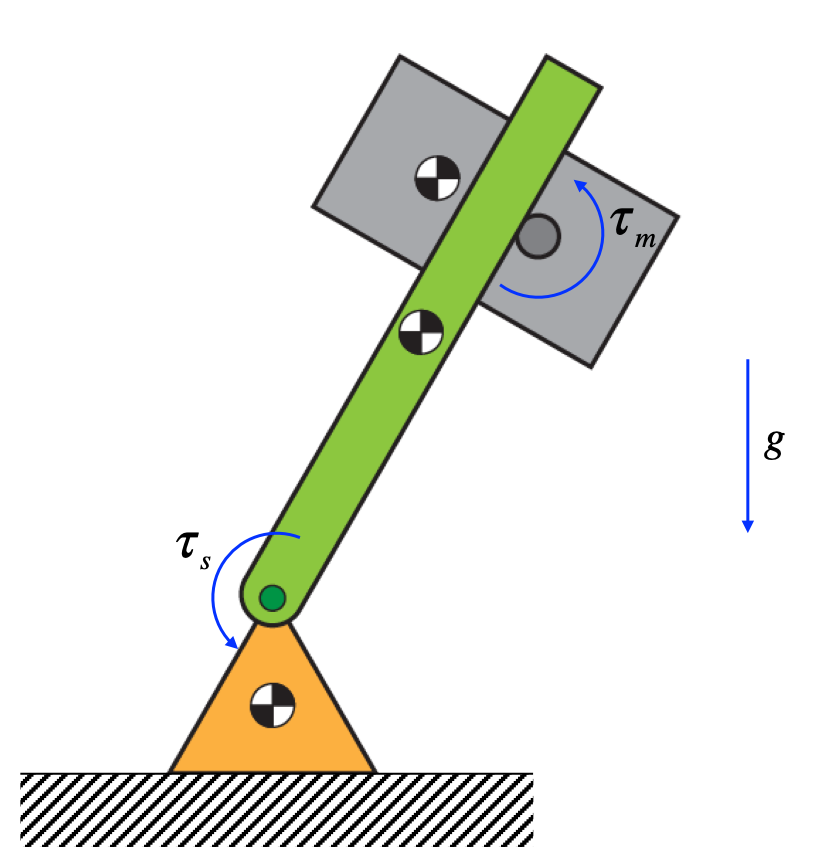

fprintf('\tInitializing generalized coordinates, velocities, accelerations, and forces...\n');

	Initializing generalized coordinates, velocities, accelerations, and forces...



% Generalized coordinates:
% x_f:  horizontal displacement of foot CoM
% z_f:  vertical displacement of foot CoM
% theta_f: angle of the foot relative to ground; positive cw
% theta_s: angle of the spine relative to foot; positive cw
% theta_m: angle of the motor; positive ccw
syms x_f z_f theta_f theta_s theta_m real
q = [x_f; z_f; theta_f; theta_s; theta_m];

% Generalized velocities:
syms x_dot_f z_dot_f theta_dot_f theta_dot_s theta_dot_m real
q_dot = [x_dot_f; z_dot_f; theta_dot_f; theta_dot_s; theta_dot_m]

$$q\_dot = \left(\begin{array}{c} {\dot{x}}_{f}\\ {\dot{z}}_{f}\\ {\dot{\theta }}_{f}\\ {\dot{\theta }}_{s}\\ {\dot{\theta }}_{m} \end{array}\right)$$


% Generalized accelerations:
syms x_ddot_f z_ddot_f theta_ddot_f theta_ddot_s theta_ddot_m real
q_ddot = [x_ddot_f; z_ddot_f; theta_ddot_f; theta_ddot_s; theta_ddot_m]

$$q\_ddot = \left(\begin{array}{c} {\ddot{x}}_{f}\\ {\ddot{z}}_{f}\\ {\ddot{\theta }}_{f}\\ {\ddot{\theta }}_{s}\\ {\ddot{\theta }}_{m} \end{array}\right)$$


% Generalized forces:
% tau_s: torque at base of spine; positive cw
% tau_m: motor torque on body motor; positive ccw
syms tau_s tau_m real 
Q = [0; 0; 0; tau_s; tau_m];

fprintf('\t...done.\n');

	...done.


## Inertial (and other) parameters

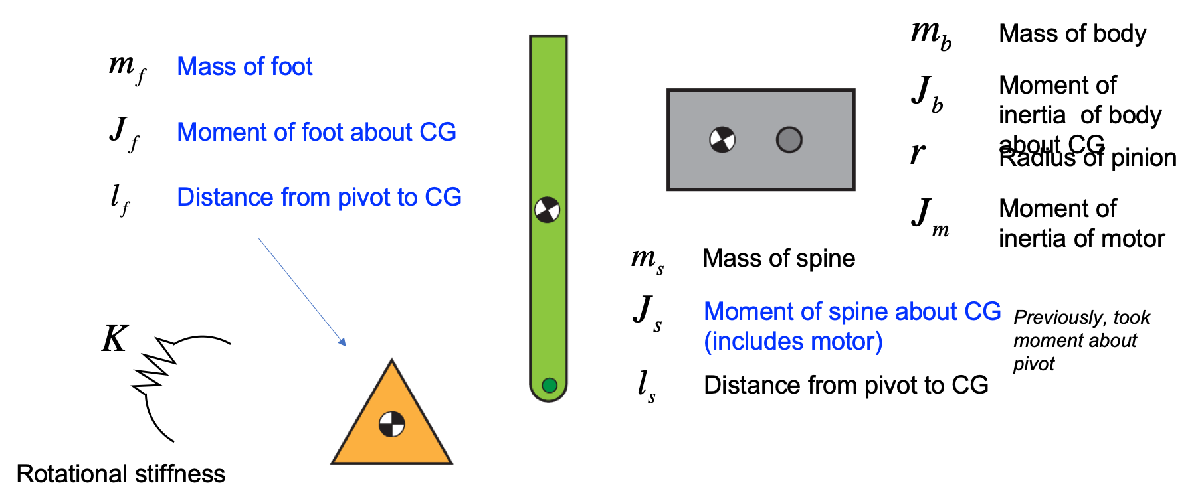

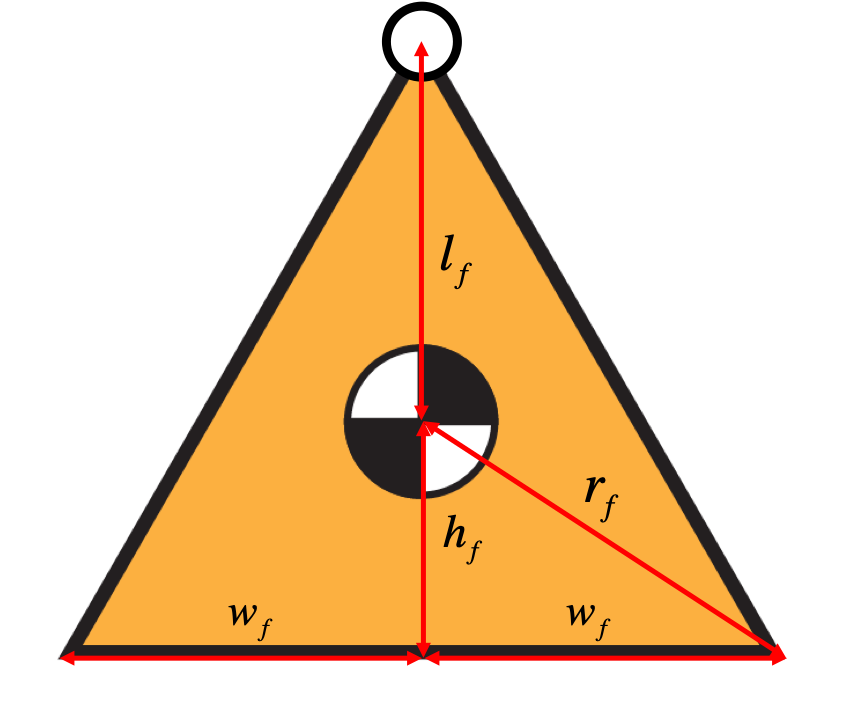

fprintf('\tInitializing inertial (and other) parameters...\n');

	Initializing inertial (and other) parameters...



% Mass of each body:
syms m_f m_s m_b real

% Rotational inertia of each component:
syms J_f J_s J_b J_m real

% Stiffness between sping and foot:
syms K real

% Geometry:
syms l_s p_b r h_f w_f l_f l_spine real

% Other variables
g = sym('g','real'); % gravity
% t = sym('t','real'); % time

fprintf('\t...done.\n');

	...done.


## Forward Kinematics

Here the goal is to find the CoM motion of the spine and body in terms of the generalized coordinates (the foot is trivial)

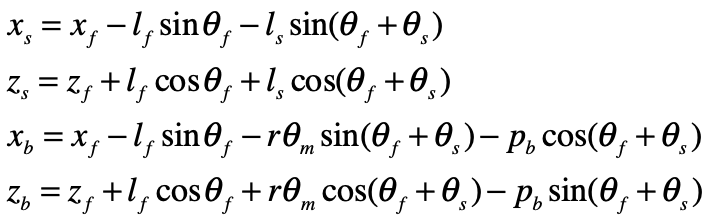

fprintf('\tInitializing kinematics variables...\n');

	Initializing kinematics variables...



% x and z coordinates of the spine and body CoM:
syms x_s z_s x_b z_b real

x_s = x_f - l_f*sin(theta_f) - l_s*sin(theta_f + theta_s);
z_s = z_f + l_f*cos(theta_f) + l_s*cos(theta_f + theta_s);
x_b = x_f - l_f*sin(theta_f) - r*theta_m*sin(theta_f + theta_s) - p_b*cos(theta_f + theta_s);
z_b = z_f + l_f*cos(theta_f) + r*theta_m*cos(theta_f + theta_s) - p_b*sin(theta_f + theta_s);

% create 2x1 arrays to hold the CoM forward kinematics (FK) outputs:
FK_com_s = [x_s; z_s];
FK_com_b = [x_b; z_b];

% coordinates of the pivot and the spine tip to help animate
syms x_pivot z_pivot x_tip z_tip real

x_pivot = x_f - l_f*sin(theta_f);
z_pivot = z_f + l_f*cos(theta_f);
x_tip = x_f - l_f*sin(theta_f) - l_spine*sin(theta_f + theta_s);
z_tip = z_f + l_f*cos(theta_f) + l_spine*cos(theta_f + theta_s);

% create 2x1 arrays to hold the Visualization forward kinematics (FK) outputs:
FK_pivot = [x_pivot; z_pivot];
FK_tip = [x_tip; z_tip];

fprintf('\t...done.\n');

	...done.


fprintf('\tGenerating forward kinematics equations...\n');

	Generating forward kinematics equations...



% generate MATLAB functions to compute all the FK outputs:
matlabFunction(FK_com_s,FK_com_b,'File','autogen_fk_com');
matlabFunction(FK_pivot,FK_tip,'File','autogen_fk_viz');
% Note: these autogenerated functions will make plotting/animation easier
% later. Could also help with some control tasks.
fprintf('\t...done.\n');

	...done.


## Constraint Equations

Here we write out the three constraint equations that are in play when the foot is planted on the ground.  The constraints come from each bottom corner not penetrating the floor, and from the foot not slipping sideways

## 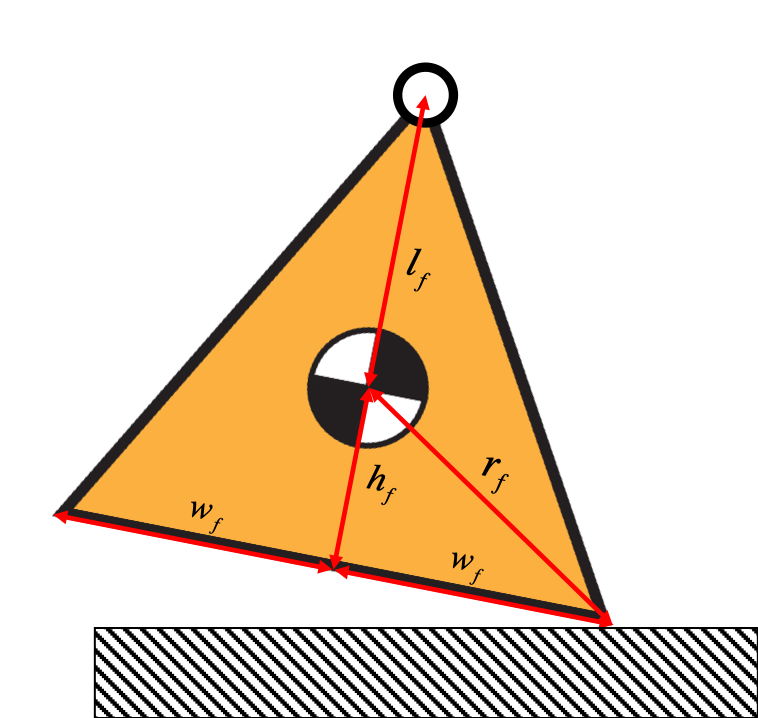

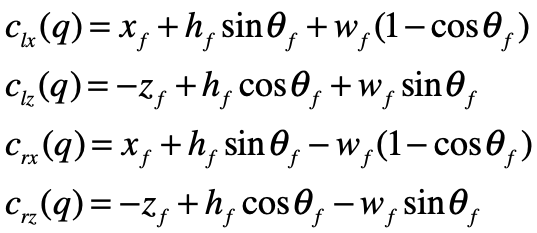

c1 is the left bottom corner.  Notice that this is different than what was in the lecture.  I added a fourth constraint equation.  Now, instead of a single equation for the x direction, we have one for each corner.  Normally, we will use only one.  It doesn't matter which one because they're redundant with one another.  If one foot lifts off, we'll then have two remaining constraint equations, and then we'll need to be sure to use the ones associated with the foot that remains on the ground.

fprintf('\tInitializing constraint variables...\n');

	Initializing constraint variables...



% three constraints variables:
syms c_lx c_lz c_rx c_rz real

c_lx = x_f + h_f*sin(theta_f) + w_f*(1 - cos(theta_f));
c_lz = -z_f + h_f*cos(theta_f) + w_f*sin(theta_f);
c_rx = x_f + h_f*sin(theta_f) - w_f*(1 - cos(theta_f));
c_rz = -z_f + h_f*cos(theta_f) - w_f*sin(theta_f);


% create 3x1 arrays to hold all constraints and forces:
C_all = [c_lx; c_lz; c_rx; c_rz];

fprintf('\t...done.\n');

	...done.


fprintf('\tGenerating constraint equations...\n');

	Generating constraint equations...



% generate MATLAB functions to compute all the constraints:
matlabFunction(C_all,'File','autogen_constraints');
fprintf('\t...done.\n');

	...done.


## Derivatives

Here we take derivatives of both the forward kinematics and the constraint equations

fprintf('\tGenerating time derivatives of the kinematics equations...\n');

	Generating time derivatives of the kinematics equations...



syms dFK_com_s dFK_com_b A_all H_clx H_clz H_crx H_crz real

% Body CoM velocities:
dFK_com_s = jacobian(FK_com_s,q)*q_dot

$$dFK\_com\_s = \left(\begin{array}{c} {\dot{x}}_{f}-{\dot{\theta }}_{f}\,\left(l_{s}\,\cos\left(\theta_{f}+\theta_{s}\right)+l_{f}\,\cos\left(\theta_{f}\right)\right)-l_{s}\,{\dot{\theta }}_{s}\,\cos\left(\theta_{f}+\theta_{s}\right)\\ {\dot{z}}_{f}-{\dot{\theta }}_{f}\,\left(l_{s}\,\sin\left(\theta_{f}+\theta_{s}\right)+l_{f}\,\sin\left(\theta_{f}\right)\right)-l_{s}\,{\dot{\theta }}_{s}\,\sin\left(\theta_{f}+\theta_{s}\right) \end{array}\right)$$

dFK_com_b = jacobian(FK_com_b,q)*q_dot

$$dFK\_com\_b = \begin{array}{l} \left(\begin{array}{c} {\dot{x}}_{f}-{\dot{\theta }}_{f}\,\left(l_{f}\,\cos\left(\theta_{f}\right)-\sigma_{3}+\sigma_{2}\right)+{\dot{\theta }}_{s}\,\left(\sigma_{3}-\sigma_{2}\right)-r\,{\dot{\theta }}_{m}\,\sin\left(\theta_{f}+\theta_{s}\right)\\ {\dot{z}}_{f}-{\dot{\theta }}_{f}\,\left(\sigma_{4}+l_{f}\,\sin\left(\theta_{f}\right)+\sigma_{1}\right)-{\dot{\theta }}_{s}\,\left(\sigma_{4}+\sigma_{1}\right)+r\,{\dot{\theta }}_{m}\,\cos\left(\theta_{f}+\theta_{s}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r\,\theta_{m}\,\sin\left(\theta_{f}+\theta_{s}\right)\\ \sigma_{2}=r\,\theta_{m}\,\cos\left(\theta_{f}+\theta_{s}\right)\\ \sigma_{3}=p_{b}\,\sin\left(\theta_{f}+\theta_{s}\right)\\ \sigma_{4}=p_{b}\,\cos\left(\theta_{f}+\theta_{s}\right) \end{array}$$


% Constraint equations first and second derivatives
A_all = jacobian(C_all,q)

$$A\_all = \left(\begin{array}{ccccc} 1 & 0 & h_{f}\,\cos\left(\theta_{f}\right)+w_{f}\,\sin\left(\theta_{f}\right) & 0 & 0\\ 0 & -1 & w_{f}\,\cos\left(\theta_{f}\right)-h_{f}\,\sin\left(\theta_{f}\right) & 0 & 0\\ 1 & 0 & h_{f}\,\cos\left(\theta_{f}\right)-w_{f}\,\sin\left(\theta_{f}\right) & 0 & 0\\ 0 & -1 & -w_{f}\,\cos\left(\theta_{f}\right)-h_{f}\,\sin\left(\theta_{f}\right) & 0 & 0 \end{array}\right)$$

H_clx = hessian(c_lx,q)

$$H\_clx = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & w_{f}\,\cos\left(\theta_{f}\right)-h_{f}\,\sin\left(\theta_{f}\right) & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

H_clz = hessian(c_lz,q)

$$H\_clz = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -h_{f}\,\cos\left(\theta_{f}\right)-w_{f}\,\sin\left(\theta_{f}\right) & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

H_crx = hessian(c_rx,q)

$$H\_crx = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -w_{f}\,\cos\left(\theta_{f}\right)-h_{f}\,\sin\left(\theta_{f}\right) & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

H_crz = hessian(c_rz,q)

$$H\_crz = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & w_{f}\,\sin\left(\theta_{f}\right)-h_{f}\,\cos\left(\theta_{f}\right) & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


% generate MATLAB functions for the Jacobians and Hessians:
matlabFunction(dFK_com_s,dFK_com_b,'File','autogen_jacobians');
matlabFunction(A_all,H_clx,H_clz,H_crx,H_crz,'File','autogen_constraint_derivatives');

fprintf('\t...done.\n');

	...done.


## Kinetic energy

Sum up:

- Foot translational

- Foot rotational

- Spine translational

- Spine rotational

- Body translational

- Body rotational

- Motor rotational

fprintf('\tGenerating kinetic energy equation...\n');

	Generating kinetic energy equation...



syms ke_f ke_s ke_b KE real

% kinetic energy of each body:
ke_f = 0.5*J_f*theta_dot_f^2 + 0.5*m_f*(x_dot_f^2 + z_dot_f^2);
ke_s = 0.5*J_s*(theta_dot_f + theta_dot_s)^2 + 0.5*m_s*(dFK_com_s'*dFK_com_s);
ke_b = 0.5*J_b*(theta_dot_f + theta_dot_s)^2 + 0.5*m_b*(dFK_com_b'*dFK_com_b) + 0.5*J_m*(theta_dot_m + theta_dot_f + theta_dot_s)^2;

% total kinetic energy:
KE = ke_f + ke_s + ke_b

$$KE = \begin{array}{l} \frac{m_{s}\,\left({\left({\dot{\theta }}_{f}\,\left(l_{s}\,\sin\left(\theta_{f}+\theta_{s}\right)+l_{f}\,\sin\left(\theta_{f}\right)\right)-{\dot{z}}_{f}+l_{s}\,{\dot{\theta }}_{s}\,\sin\left(\theta_{f}+\theta_{s}\right)\right)}^{2}+{\left({\dot{\theta }}_{f}\,\left(l_{s}\,\cos\left(\theta_{f}+\theta_{s}\right)+l_{f}\,\cos\left(\theta_{f}\right)\right)-{\dot{x}}_{f}+l_{s}\,{\dot{\theta }}_{s}\,\cos\left(\theta_{f}+\theta_{s}\right)\right)}^{2}\right)}{2}+\frac{J_{b}\,{\left({\dot{\theta }}_{f}+{\dot{\theta }}_{s}\right)}^{2}}{2}+\frac{J_{s}\,{\left({\dot{\theta }}_{f}+{\dot{\theta }}_{s}\right)}^{2}}{2}+\frac{J_{f}\,{{\dot{\theta }}_{f}}^{2}}{2}+\frac{m_{b}\,\left({\left({\dot{x}}_{f}-{\dot{\theta }}_{f}\,\left(l_{f}\,\cos\left(\theta_{f}\right)-\sigma_{3}+\sigma_{2}\right)+{\dot{\theta }}_{s}\,\left(\sigma_{3}-\sigma_{2}\right)-r\,{\dot{\theta }}_{m}\,\sin\left(\theta_{f}+\theta_{s}\right)\right)}^{2}+{\left({\dot{z}}_{f}-{\dot{\theta }}_{f}\,\left(\sigma_{4}+l_{f}\,\sin\left(\theta_{f}\right)+\sigma_{1}\right)-{\dot{\theta }}_{s}\,\left(\sigma_{4}+\sigma_{1}\right)+r\,{\dot{\theta }}_{m}\,\cos\left(\theta_{f}+\theta_{s}\right)\right)}^{2}\right)}{2}+\frac{J_{m}\,{\left({\dot{\theta }}_{f}+{\dot{\theta }}_{m}+{\dot{\theta }}_{s}\right)}^{2}}{2}+\frac{m_{f}\,\left({{\dot{x}}_{f}}^{2}+{{\dot{z}}_{f}}^{2}\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=r\,\theta_{m}\,\sin\left(\theta_{f}+\theta_{s}\right)\\ \sigma_{2}=r\,\theta_{m}\,\cos\left(\theta_{f}+\theta_{s}\right)\\ \sigma_{3}=p_{b}\,\sin\left(\theta_{f}+\theta_{s}\right)\\ \sigma_{4}=p_{b}\,\cos\left(\theta_{f}+\theta_{s}\right) \end{array}$$


fprintf('\t...done.\n');

	...done.


## Potential energy

Sum up:

- Gravitational potential of foot

- Gravitational potential of spine

- Gravitational potential of body

- Spring

Note:  does not include virtual work done by constraints

fprintf('\tGenerating potential energy equation...\n');

	Generating potential energy equation...



syms pe_f pe_s pe_b pe_spring real

% potential energy of each body:
pe_f = m_f*g*(z_f - h_f);
pe_s = m_s*g*(z_s - l_s - l_f - h_f);
pe_b = m_b*g*(z_b - l_f - h_f);
pe_spring = 0.5*K*theta_s^2;

% total potential energy:
PE = pe_f + pe_s + pe_b + pe_spring

$$PE = \frac{K\,{\theta_{s}}^{2}}{2}-g\,m_{b}\,\left(h_{f}+l_{f}-z_{f}+p_{b}\,\sin\left(\theta_{f}+\theta_{s}\right)-l_{f}\,\cos\left(\theta_{f}\right)-r\,\theta_{m}\,\cos\left(\theta_{f}+\theta_{s}\right)\right)-g\,m_{s}\,\left(h_{f}+l_{f}+l_{s}-z_{f}-l_{s}\,\cos\left(\theta_{f}+\theta_{s}\right)-l_{f}\,\cos\left(\theta_{f}\right)\right)-g\,m_{f}\,\left(h_{f}-z_{f}\right)$$


fprintf('\t...done.\n');

	...done.


## Euler-Lagrange equations

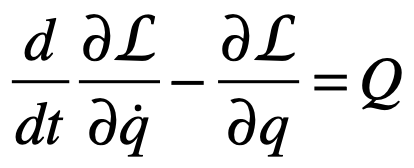

fprintf('\tGenerating Euler-Lagrange equations of motion...\n')

	Generating Euler-Lagrange equations of motion...



% Variable initializations:
del_L_del_qdot = sym('del_L_del_qdot',[numel(q),1],'real'); % del L/del q_dot
ELeq_term1  = sym('ELeq_term1',[numel(q),1],'real'); % d(del L/del dq)/dt
ELeq_term2  = sym('ELeq_term2',[numel(q),1],'real'); % del L/del q

del_L_del_qdot = jacobian(KE,q_dot)';
ELeq_term1 = simplify(jacobian(del_L_del_qdot,[q;q_dot])*[q_dot;q_ddot])

ELeq_term2 = simplify(jacobian((KE-PE),q))'

% Note: no constraint forces yet

fprintf('\t...done.\n')

	...done.


## Finding the mass matrix

Note: the highest order derivative that shows up in the Euler-Lagrange Equations is second:  q_ddot  (accelerations).  Our goal is to obtain equations for q_ddot in terms of the state q, state derivatives q_dot, and generalized forces (i.e., the motor torques) Q.  These equations can then be integrated forward in time.  Fortunately, the accelerations always show up linearly and the matrix that multiplies them, the "mass matrix" is guaranteed to be invertible:

      M(q)*q_ddot + H(q,q_dot) = Q

Note that this equation is a generalization of F=ma. It represents the *inverse* dynamics, mapping positions, velocities, and accelerations of the joints to forces or torques (depending on the nature of each joint).

Important note:  there is additional structure in H that is often important to know about.  We won't go into that here.

fprintf('\tSolving for the mass matrix...\n');

	Solving for the mass matrix...



M = sym('M',[numel(q),numel(q)],'real');
H = sym('H',[numel(q),1],'real');

M = simplify(jacobian(del_L_del_qdot,q_dot))

H = simplify(jacobian(del_L_del_qdot,q)*q_dot - ELeq_term2)


fprintf('\t\t...done building M and H.\n');

		...done building M and H.


Note: we need inv(M) to compute the fwd. dynamics and therefore the state-space dynamics (see below), so to ease computation cost we derive inv(M) symbolically here and autogenerate a dedicated MATLAB function for evaluating it.


% compute and store inv(M):
fprintf('\t\tComputing inv(M)...\n')

		Computing inv(M)...


Minv = sym('Minv',[numel(q),numel(q)],'real');
Minv = simplify(inv(M))

fprintf('\t\t...done.\n')

		...done.



fprintf('\t\tGenerating MATLAB functions...\n');

		Generating MATLAB functions...


matlabFunction(M,'File','autogen_mass_matrix');
matlabFunction(Minv,'File','autogen_inverse_mass_matrix');
matlabFunction(H,'File','autogen_H_eom');
fprintf('\t\t...done.\n');

		...done.


## Constraint Forces

This will all be handled in robot_dynamics.m ... no need for symbolic manipulation just to multiply or invert matrices!

## Generate (nonlinear) state-space model from manipulator equation

This will also be handled in robot_dynamics.m

## Done!

fprintf('...done deriving cart-pendulum equations.\n');

...done deriving cart-pendulum equations.
